% Read CSV as text to preserve hex values
opts = detectImportOptions('RECEIVEANDTRANSMIT.csv');
opts = setvartype(opts, 'char');   % all columns as text
rawData = readtable('RECEIVEANDTRANSMIT.csv', opts);

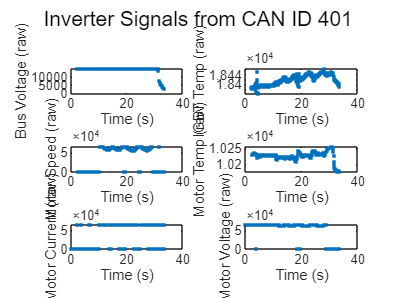


% Skip header (first 7 rows)
rawData = rawData(8:end,:);

% Convert relevant columns
time   = str2double(rawData{:,1});      % timestamp
canID  = hex2dec(rawData{:,3});         % CAN ID in decimal
byte0  = hex2dec(rawData{:,6});         % first payload byte (signal ID)
byte1  = hex2dec(rawData{:,7});         % low byte of value
byte2  = hex2dec(rawData{:,8});         % high byte of value

% Build 16-bit value (assuming little endian: byte1 = LSB, byte2 = MSB)
value16 = byte1 + 256*byte2; %little endian
%value16 = 256*byte1 + byte2; %big endian

% Only look at inverter CAN frames (ID = 400 decimal = 0x190)
mask = (canID == 401);

% Preallocate result arrays (same length as data, NaN when not present)
busVoltage     = NaN(size(value16));
igbtTemp       = NaN(size(value16));
motorSpeed     = NaN(size(value16));
motorTemp      = NaN(size(value16));
motorCurrent   = NaN(size(value16));
motorVoltage   = NaN(size(value16));

% Decode depending on byte0
busVoltage(mask & byte0 == 235)   = value16(mask & byte0 == 235);
igbtTemp(mask & byte0 == 74)      = value16(mask & byte0 == 74);
motorSpeed(mask & byte0 == 168)   = value16(mask & byte0 == 168);
motorTemp(mask & byte0 == 73)     = value16(mask & byte0 == 73);
motorCurrent(mask & byte0 == 95)  = value16(mask & byte0 == 95);
motorVoltage(mask & byte0 == 138) = value16(mask & byte0 == 138);

figure;

subplot(3,2,1);
plot(time, busVoltage, '.-')
xlabel('Time (s)'); ylabel('Bus Voltage (raw)');

subplot(3,2,2);
plot(time, igbtTemp, '.-')
xlabel('Time (s)'); ylabel('IGBT Temp (raw)');

subplot(3,2,3);
plot(time, motorSpeed, '.-')
xlabel('Time (s)'); ylabel('Motor Speed (raw)');

subplot(3,2,4);
plot(time, motorTemp, '.-')
xlabel('Time (s)'); ylabel('Motor Temp (raw)');

subplot(3,2,5);
plot(time, motorCurrent, '.-')
xlabel('Time (s)'); ylabel('Motor Current (raw)');

subplot(3,2,6);
plot(time, motorVoltage, '.-')
xlabel('Time (s)'); ylabel('Motor Voltage (raw)');

sgtitle('Inverter Signals from CAN ID 401');  % overall title

% Read CSV as text to preserve hex values
opts = detectImportOptions('RECEIVEANDTRANSMIT.csv');
opts = setvartype(opts, 'char');   % all columns as text
rawData = readtable('RECEIVEANDTRANSMIT.csv', opts);

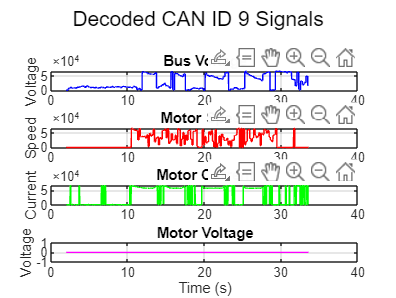


% Skip header (first 7 rows)
rawData = rawData(8:end,:);

% Convert relevant columns
time   = str2double(rawData{:,1});      % timestamp
canID  = hex2dec(rawData{:,3});         % CAN ID in decimal

% Extract payload bytes as numeric
byte0  = hex2dec(rawData{:,6});
byte1  = hex2dec(rawData{:,7});
byte2  = hex2dec(rawData{:,8});
byte3  = hex2dec(rawData{:,9});
byte4  = hex2dec(rawData{:,10});
byte5  = hex2dec(rawData{:,11});
byte6  = hex2dec(rawData{:,12});
byte7  = hex2dec(rawData{:,13});

%% Filter messages for CAN ID = 9
mask9 = (canID == 9);

time_9  = time(mask9);
byte0_9 = byte0(mask9);
byte1_9 = byte1(mask9);
byte2_9 = byte2(mask9);
byte3_9 = byte3(mask9);
byte4_9 = byte4(mask9);
byte5_9 = byte5(mask9);
byte6_9 = byte6(mask9);
byte7_9 = byte7(mask9);

%% Decode signals (little-endian: low byte first)
busVoltagetx   = byte0_9 + 256*byte1_9;
motorSpeedtx   = byte2_9 + 256*byte3_9;
motorCurrenttx = byte4_9 + 256*byte5_9;
motorVoltagetx = byte6_9 + 256*byte7_9;


%% Plot all four signals over time
figure('Name','CAN ID 9 Signals','NumberTitle','off');

subplot(4,1,1)
plot(time_9, busVoltagetx, 'b')
title('Bus Voltage')
ylabel('Voltage')
grid on

subplot(4,1,2)
plot(time_9, motorSpeedtx, 'r')
title('Motor Speed')
ylabel('Speed')
grid on

subplot(4,1,3)
plot(time_9, motorCurrenttx, 'g')
title('Motor Current')
ylabel('Current')
grid on

subplot(4,1,4)
plot(time_9, motorVoltagetx, 'm')
title('Motor Voltage')
ylabel('Voltage')
xlabel('Time (s)')
grid on

sgtitle('Decoded CAN ID 9 Signals')

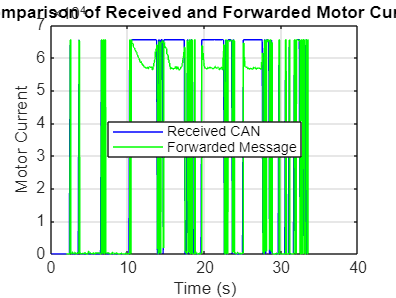

figure;

% Example: motorCurrent and time are same length vectors
validMask = ~isnan(motorCurrent);     % logical mask for non-NaN entries

% Keep only the valid samples
time_valid = time(validMask);
motorCurrent_valid = motorCurrent(validMask);

% Plot

figure;
plot(time_valid, motorCurrent_valid, 'b', 'DisplayName', 'Received CAN');
hold on;
plot(time_9, motorCurrenttx, 'g', 'DisplayName', 'Forwarded Message');
hold off;

xlabel('Time (s)');
ylabel('Motor Current');
title('Comparison of Received and Forwarded Motor Current');
legend('Location', 'best');
grid on;

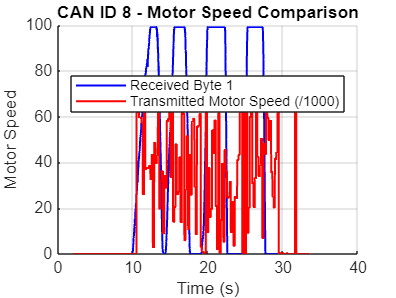

% --- Filter for CAN ID 8 ---
mask8 = (canID == 8);

time_8  = time(mask8);
byte1_8 = byte1(mask8);

% --- Remove NaN values just in case ---
validMask = ~isnan(time_8) & ~isnan(byte1_8);
time_8  = time_8(validMask);
byte1_8 = byte1_8(validMask);

% --- Plot byte 1 for ID 8 ---
figure;
hold on;

% Received data
plot(time_8, byte1_8, 'b', 'LineWidth', 1.2);

% Transmitted data (scaled)
plot(time_8, motorSpeedtx/1000, 'r', 'LineWidth', 1.2);

% Labels and title
xlabel('Time (s)');
ylabel('Motor Speed');
title('CAN ID 8 - Motor Speed Comparison');
grid on;

% Legend including scaling factor
legend('Received Byte 1', 'Transmitted Motor Speed (/1000)', 'Location', 'best');

hold off;